# Problema 3 - Practic

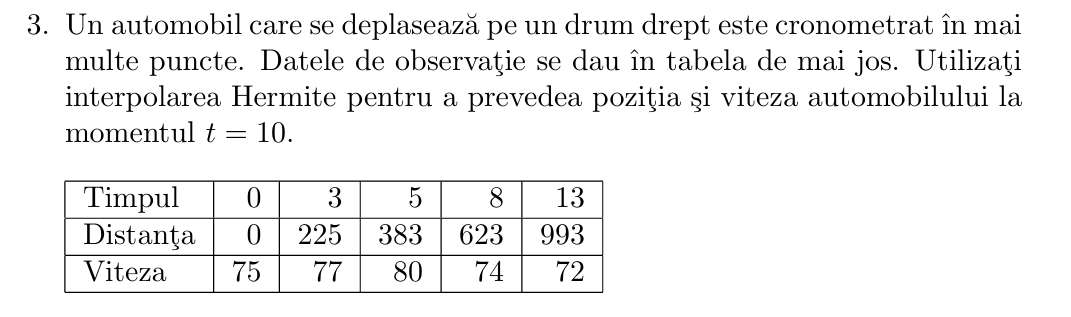

% PB1
function [p_val, coef, z] = interpolareHermite(x, f, df, x_eval)
% INTERPOLAREHERMITE - Interpolare Hermite cu noduri duble (forma Newton)
%
% INPUT:
%   x       - vector cu nodurile xi (lungime n)
%   f       - valorile functiei f(xi)
%   df      - valorile derivatei f'(xi)
%   x_eval  - punctele in care se evalueaza polinomul
%
% OUTPUT:
%   p_val   - valorile interpolate in punctele x_eval
%   coef    - coeficientii Newton ai polinomului Hermite
%   z       - vectorul de noduri extinse (cu dubluri)

    n = length(x);        % numarul de noduri initiale
    m = 2 * n;            % numarul de linii in tabela (fiecare nod apare de 2 ori)
    
    z = zeros(1, m);      % vectorul de noduri extinse: z_0, z_1, ..., z_{2n-1}
    Q = zeros(m, m);      % tabela Hermite de diferente divizate

    % P1, P2 
    for i = 1:n
        z(2*i - 1) = x(i);               
        z(2*i)     = x(i);              
        
        Q(2*i - 1, 1) = f(i);            
        Q(2*i,     1) = f(i);          
        
        Q(2*i,     2) = df(i);           

        % P3 - Daca nu suntem pe primul nod, calculam Q_{2i,1} 
        if i ~= 1
            Q(2*i - 1, 2) = (Q(2*i - 1, 1) - Q(2*i - 2, 1)) / ...
                           (z(2*i - 1) - z(2*i - 2));
        end
    end

    % P4 - Completam tabela Hermite (diferente divizate de ordin superior) 
    for i = 3:m
        for j = 3:i
            Q(i,j) = (Q(i,j-1) - Q(i-1,j-1)) / (z(i) - z(i-j+1));
        end
    end

    % P5 - Extragem coeficientii de pe diagonala
    coef = diag(Q);  % coeficientii din forma Newton

    % Evaluare polinom Hermite in punctele x_eval 
    p_val = zeros(size(x_eval));  % vector rezultat

    for k = 1:length(x_eval)
        val = coef(1);             % pornim cu primul coeficient
        produs = 1;

        for j = 2:m
            produs = produs * (x_eval(k) - z(j-1));
            val = val + coef(j) * produs;
        end

        p_val(k) = val;
    end
end

% Datele problemei
t = [0, 3, 5, 8, 13];           % momentele de timp
dist = [0, 225, 383, 623, 993]; % distantele
vel = [75, 77, 80, 74, 72];     % vitezele

% Evaluam polinomul Hermite in t = 10
t_eval = 10;

% Estimarea pozitiei (folosind distanta ca f, viteza ca f')
[pos10, coef, z] = interpolareHermite(t, dist, vel, t_eval);

% Derivata polinomului Hermite (pentru viteza la t=10)
% Vom folosi o aproximare numerica:
h = 1e-4;
[pos_plus, coefplus, zplus] = interpolareHermite(t, dist, vel, t_eval + h);
[pos_minus, coefminus, zminus] = interpolareHermite(t, dist, vel, t_eval - h);
vel10 = (pos_plus - pos_minus) / (2*h);  % derivata centrata

% Afisare rezultate
fprintf('Pozitie estimata la t = 10: %.4f metri\n', pos10);

Pozitie estimata la t = 10: 742.5028 metri


fprintf('Viteza estimata  la t = 10: %.4f m/s\n', vel10);

Viteza estimata  la t = 10: 48.3817 m/s
